# `Activity 4`

`Create Mel Filter Banks`

f_min = 1000;
f_max = 8000;
n_bands = 6;

mel_min = round(freq2mel(f_min))

mel_min = 1000

mel_max = round(freq2mel(f_max))

mel_max = 2840

bound_range = linspace(mel_min,mel_max,n_bands+1)

bound_range = 	1.0e+03 *

    1.0000    1.3067    1.6133    1.9200    2.2267    2.5333    2.8400



center_mel_freqs = zeros(1,n_bands)

center_mel_freqs =      0     0     0     0     0     0


for i=1:length(bound_range)-1
    center_mel_freqs(i) = round((bound_range(i)+bound_range(i+1))/2);
end

disp(center_mel_freqs)

        1153        1460        1767        2073        2380        2687



i = 2

i = 2

x = [bound_range(i),center_mel_freqs(i),bound_range(i+1)]

x = 	1.0e+03 *

    1.3067    1.4600    1.6133


y = [0,1,0]

y =      0     1     0


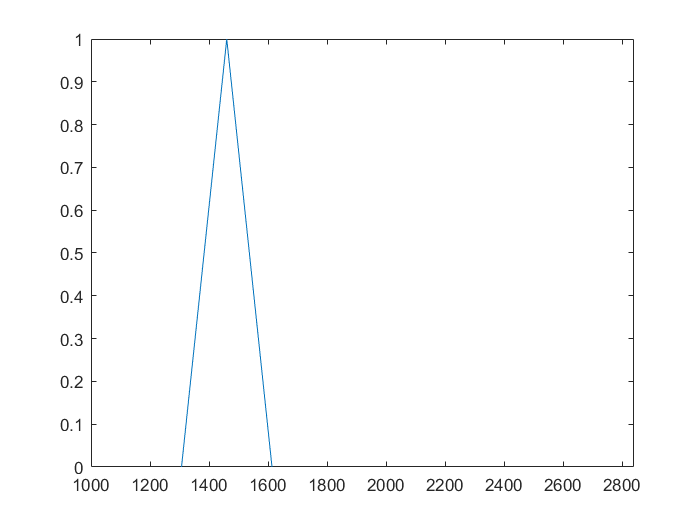

plot(x,y)
axis([bound_range(1) bound_range(end) 0 1])

figure()
for i=1:n_bands
    x = [bound_range(i),center_mel_freqs(i),bound_range(i+1)]
    y = [0,1,0]
    plot(x,y,'LineWidth',3)
    hold on
    axis([bound_range(1) bound_range(end) 0 1]) 
    xticks(round(bound_range))
end

x = 	1.0e+03 *

    1.0000    1.1530    1.3067


y =      0     1     0


x = 	1.0e+03 *

    1.3067    1.4600    1.6133


y =      0     1     0


x = 	1.0e+03 *

    1.6133    1.7670    1.9200


y =      0     1     0


x = 	1.0e+03 *

    1.9200    2.0730    2.2267


y =      0     1     0


x = 	1.0e+03 *

    2.2267    2.3800    2.5333


y =      0     1     0


x = 	1.0e+03 *

    2.5333    2.6870    2.8400


y =      0     1     0


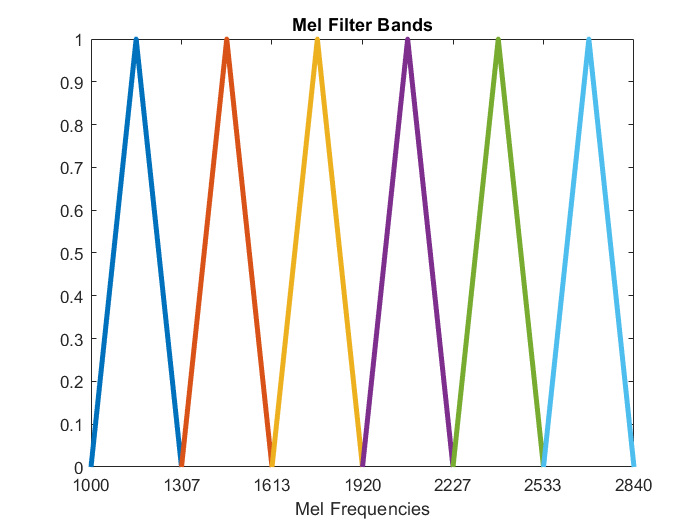

xlabel('Mel Frequencies')
title('Mel Filter Bands')

function mel = freq2mel(freq)
    mel = 2595*log10(1+(freq/700));
end

function freq = mel2freq(mel)
    freq = 700*(10^(mel/2595)-1);
end